# Trinamic TMCM-6212 tuner controler

Nathan Runggaldier 2023 / TU Wien / EMCE

## Parameter setup

% for reference see pictures below

%Communication settings
freeports = serialportlist("all");
port = freeports(1);             % select connected port
motor = 0;            % select the motor to be set

% most important settings. Check required!
v_max = 51200;               % maximum velocity [pps]
max_accel = 10000;           % maximum acceleration [pps^2]
max_curr = 0.2;    % [A] maximum peak current of the motor
standby_curr =0.01; % [A] standby current of the motor. Value should be as low as possible!

% other settings
max_decel = 20000;           % deceleration [pps^2]s
v1 = 0;                  % [pps] if set to 0, a1 and d1 are deactivated, only max_accel and max_decel used.
wait_time =0.92;   % [seconds] waiting time after ramping down to v = 0 before next movement

% necessary only in position mode
v_stop = 50;   % [pps]
v_start = 40;  % [pps]
a1 = 15000;       % [pps^2] ignored if v1 = 0
d1 = 30000;       % [pps^2] ignored if v1 = 0

 

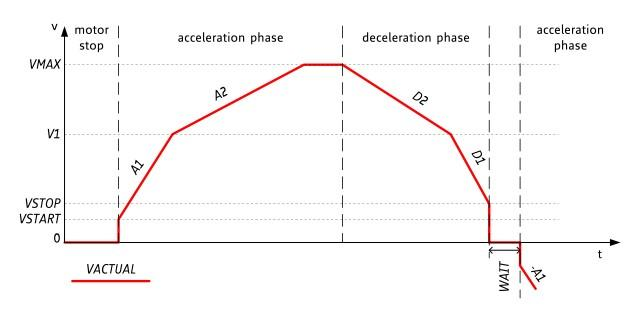

% additional calculations
wait_time = wait_time / 0.000032;
max_curr = max_curr * 170;
standby_curr = standby_curr * 170;

disp('Available ports: ');

Available ports: 


disp(freeports);

COM4


if isempty(freeports)
    error('No available serial ports found.');
end

% generate command
% byte1 - adress
main_axis_param_db = [4, 5, 6, 7, 15, 16, 17, 18, 19, 20, 21]

main_axis_param_db =      4     5     6     7    15    16    17    18    19    20    21



for x = main_axis_param_db

    if x == 4
        n = v_max;
    elseif x == 5
        n = max_accel;
    elseif x == 6
        n = max_curr;
    elseif x == 7
        n = standby_curr;
    elseif x == 15
        n = a1;
    elseif x == 16
        n = v1;
    elseif x == 17
        n = max_decel;
    elseif x == 18
        n = d1;
    elseif x == 19
        n = v_start;
    elseif x == 20
        n = v_stop;
    elseif x == 21
        n = wait_time;
    else
        error('Something went wrong.');
    end

%     disp(['n = ',num2str(n)]);

    n = int32(n);

    byte(1:4) = uint8([1,4,x,motor]);
    byte(5)= uint8(bitand(bitshift(n,-24),255) );
    byte(6)= uint8(bitand(bitshift(n,-16),255) );
    byte(7)= uint8(bitand(bitshift(n,-8),255) );
    byte(8)= uint8(bitand(n,255) );
    byte(9)=uint8(bitand(sum(byte(1:8)),255) ),

    %      disp(['Byte array for x = ', num2str(x)]);
    %     disp(byte);


    % open com port for data transfer
    fid = serialport(port, 9600, 'DataBits', 8, 'Parity', 'none', 'StopBits', 1, 'FlowControl', 'none', 'Timeout', 10);

    %send command
    write(fid, byte, "uint8");

    %get answer
    answer = read(fid, 9, 'uint8');
    disp(answer);

    % close com port connection
    close(fid);

end

byte = 1×9 uint8 row vector
     1     4     4     0     0     0   200     0   209


Error using serialport
Unable to connect to the serialport device at port 'COM4'. Verify that a device is connected to the port, the port is not in use,
and all serialport input arguments and parameter values are supported by the device.
See related documentation for troubleshooting steps.

## Initialise all motors

 

% L --> 100
% P1 und P2 --> 5000
% use search mode 2

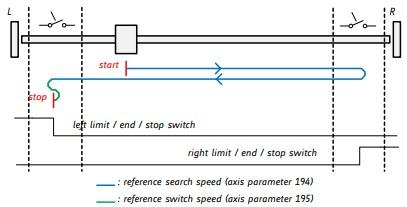

## Data transfer

% open com port for data transfer 
fid = serialport(port, 9600, 'DataBits', 8, 'Parity', 'none','StopBits', 1, 'FlowControl', 'none', 'Timeout', 10); 
open (fid); 
 
%send command 
write(fid,byte); 
 
%get answer 
answer = read(fid, 9, 'uint8');
disp(answer);
 
% close com port connection 
close(fid); 

## Functions

%% Move right


function move_right(nin) 
n = int32(nin); 
 
% generate command 
% byte1 - adress 
byte(1:4) = uint8([1,4,1,0]); 
byte(5)= uint8(bitand(bitshift(n,-24),255) ); 
byte(6)= uint8(bitand(bitshift(n,-16),255) ); 
byte(7)= uint8(bitand(bitshift(n,-8),255) ); 
byte(8)= uint8(bitand(n,255) ); 
byte(9)=uint8(bitand(sum(byte(1:8)),255) ), 
 

 
% when you enter the function " move_right(1, 0.005,0.01)" in your 
% window command, the motor can move. 
end